# Assignment Victoria Lake level modelling (OOP)

*Andrei Kedich*

## Downoading the data

tic
clearvars
catchments = shaperead('Victoria_Catchments.shp');
precip = readtable('precipitation_obs.csv');

[lc_tif, ~] = readgeoraster('lc_Victoria.tif', 'OutputType','uint8');
[soil_tif, ~] = readgeoraster('soil_Victoria.tif');
[catchments_tif, ~] = readgeoraster('Catchments_Rasterized.tif', 'OutputType','uint8');

format long

## Creation of river objects

Firstly we create an empty river array and then fill it with the river objects through the loop from catchment shapefile.

river_array = river.empty(30,0);

for i = 1:length(catchments)
    field = struct2cell(catchments(i));
    field{3} = rmmissing(field{3});
    field{4} = rmmissing(field{4});
    river_array(i) = river(field{5},field{3}, field{4}, field{6}, ...
               field{7}, field{8}, field{9}, field{10}, field{11});
end 
clear field i catchments

## Creation of lake object

On this step the lake object is created. Lake object on this step store precipiation values. Automatically inside the class evaporation is caluclated and difference between precipitation and evaporation. Moreover, we are filling nan value linearly in the data and provide smoothening by moving average of 10 values.

precip(:,2) = fillmissing(precip(:,2), 'linear'); %remove nans and fill with values
Victoria = lake(table2array(precip(:,1)), movmean(table2array((precip(:,2))), 10)); %smoothern precipitation with moving average 10

## Creation of environment object

Creation of environment object that store the information about landcover, soil and catchment rasters.

Victoria_env = environment(lc_tif, soil_tif, catchments_tif);
clear soil_tif lc_tif precip

## Calculation of inflow for first 5 days based on constant Q

On this the matrix is created for runoff per every cathment. Further, we caclaulte the inflow in the river for first 5 days as it based on the constant Q values. We are considering only rivers that flows into the lake, as their runoff already takes into account input from tributaries, furthermore human intake is already included in the value and should not be corrected (as the value represent the Q and the outlet from the gauging station)

%matrix with runoff for all rivers for every day created
%will be filled with only first 5 days
%we need first days river-by-river for lag calculation
lake_inflow_matrix = zeros(length(Victoria.precipitation), 30);

% Calculation for the first 5 days inflow
const_runoff = zeros(30, 1);

for i = 1:(length(river_array))
    if get(river_array(i), "riv_id") ~= 32
    const_runoff(get(river_array(i), "riv_id")) = get(river_array(i), "riv_q");
    end
end

for k = 1:5
    value = 0;
    lake_inflow_matrix(k,:) = const_runoff;
    for i = 1:length(river_array)
        value = value + river_array(i).stable_inflow(lake_inflow_matrix);
    end
    Victoria.inflow(k, 1) = value; %.stable_inflow(river_array, lake_inflow_matrix);
end  
%inflow for first 5 days calculated

clear const_runoff i k

## Caclulation the inflow matrix without time lag accounting

The main part of the conde that step by step for every day starting the 6 day calculated soil_retention matrix for every cell, followingly runoff for every cell is calculated. On the next step runoff summed up for cathments and water use is accounted for every cathment.

Further, the time lag is implemented through non_stableinflow function by adding values to the next row in the matrix.Finally, the inflow that flows into the lake is summed and added to the lake object.

for m = 6:length(Victoria.time)
        Soil_retention = Victoria_env.define_SoilRetention(Victoria, m);
        runoff_overtime = river.calculate_runoff(Soil_retention, Victoria, m);
        rfcm_time = river.rf_catchment(catchments_tif, runoff_overtime);
        for k = 2:length(river_array)
           rfcm_time(get(river_array(k), "riv_id")) = river_array(k).water_use(rfcm_time);
        end 
        lake_inflow_matrix(m, :) = rfcm_time;
        lake_inflow_matrix(m, :) = river.non_stableinflow(river_array, lake_inflow_matrix, m);
        Victoria.inflow(m) = river.inflow_sum(river_array, lake_inflow_matrix(m, :));
end 

Victoria.inflow = fillmissing(Victoria.inflow, 'linear');

clear Soil_retention runoff_overtime rfcm_time catchments_tif lake_inflow_matrix

## Victoria level retrieval

This part of code is dedicated to exact retrieval of lake level based on previosly calculated inflow and precipitation, evaporation and outflow. Also outflow values are calculated for further visualization.

Victoria.level(1) = 1135;
for i = 2:length(Victoria.time)
    Victoria.level(i) = Victoria.water_balance(i-1);
    Victoria.outflow(i) = Victoria.lake_outflow(i);
end

## Plotting figures

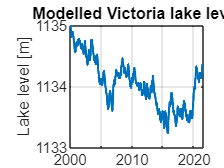

figure(1)
plot(get(Victoria, "time"), get(Victoria, "level"), "LineWidth", 1.3)
grid("on")
ylabel("Lake level [m]")
title("Modelled Victoria lake level")

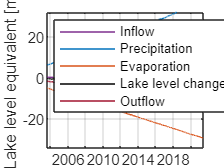


rel_level = zeros(length(Victoria.level),1);
for i = 1:length(Victoria.level)
    rel_level(i) = (Victoria.level(i)) - 1135;
end 

figure(2)
plot(Victoria.time, (cumsum((Victoria.inflow/(6.83e10)))),'DisplayName','Inflow', Color=[0.4940 0.1840 0.5560])
hold on
plot(Victoria.time, (cumsum(Victoria.precipitation)/1000), 'g','DisplayName','Precipitation', Color=[0 0.4470 0.7410])
hold on
plot(Victoria.time, -(cumsum(Victoria.evaporation)/1000),'DisplayName','Evaporation', Color=[0.8500 0.3250 0.0980])
hold on
plot(Victoria.time, rel_level, 'black','DisplayName','Lake level change')
hold on
plot(Victoria.time, -(cumsum((Victoria.outflow/(6.83e10)))), 'r','DisplayName','Outflow', Color=[0.6350 0.0780 0.1840])
grid("on")
legend('Location','northwest')
ylabel("Lake level equivalent [m]")


time_taken=toc;
disp("Time: " + time_taken)

Time: 1314.4054


Limitations: according to the paper observed inflow is larger than in our modelled scenario, that could result in a higher lake level. However, here the main dynamics is described by the precipitation as well. But the role of precipitation is higher. Furthermore, precipiation/evaporation balance in our scenario is postive and precipitation from the lake mirror is higher that evaporation.

These inconsistincies might be related to the miscalculations process of inflow. For this purpose the algorithm should be revised.